# One-dimensional quadratic basis functions

Construction of the linear one-dimensional basis functions (alternative known as hat basis functions) using the one-dimensional [Lagrange polynomials](https://en.wikipedia.org/wiki/Lagrange_polynomial).

Go to [THIS](matlab:open('./main_Chapter1_BasisFunctions.mlx')) Section in the main driver script *One-dimensional quadratic basis functions*

Go to [PREVIOUS](matlab:open('./main_Chapter11_OneDimensionalLinearBasisFunctions.mlx')) Section One*-dimensional linear basis functions*

Go to [NEXT](matlab:open('./main_Chapter13_TwoDimensionalBilinearBasisFunctions.mlx')) Section *Two-dimensional bilinear basis functions*

**Author: Dr.-Ing. Andreas Apostolatos**

**Date: 22.12.2022**

## Preamble

vars = "mshL2";
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter01_OneDimensionalLinearBasisFunctions.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Quadratic Lagrange Polynomials

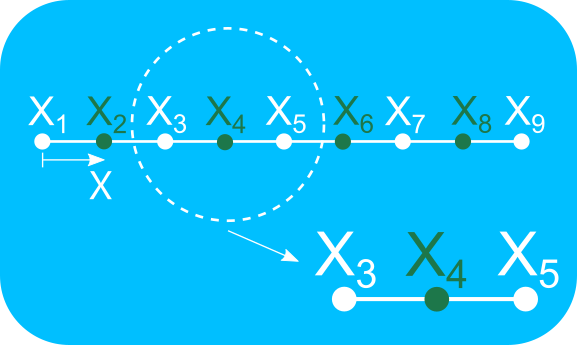

syms l1L2(X, X1, X2, X3) l2L2(X, X1, X2, X3) l3L2(X, X1, X2, X3)
l1L2(X, X1, X2, X3) = (X - X2)/(X1 - X2)*(X - X3)/(X1 - X3);
l2L2(X, X1, X2, X3) = (X - X1)/(X2 - X1)*(X - X3)/(X2 - X3);
l3L2(X, X1, X2, X3) = (X - X1)/(X3 - X1)*(X - X2)/(X3 - X2);

## Visualization of the one-dimensional quadratic Lagrange Polynomials in the physical space of  the mesh

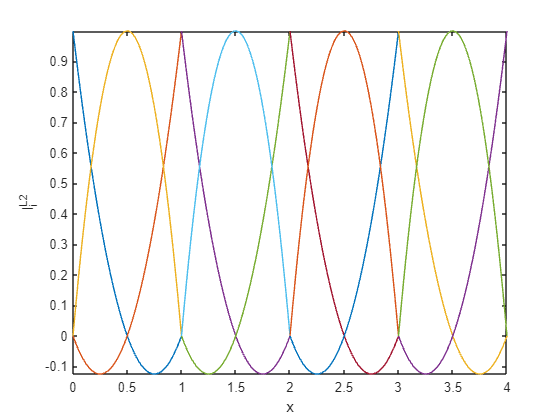

figure,
for ii = 1: numel(mshL2.elements(:, 1))
    nodesEl = mshL2.nodes(mshL2.elements(ii, :));
    fplot([l1L2(X, nodesEl(1, 1), nodesEl(2, 1), nodesEl(3, 1)) ...
        l2L2(X, nodesEl(1, 1), nodesEl(2, 1), nodesEl(3, 1)) ...
        l3L2(X, nodesEl(1, 1), nodesEl(2, 1), nodesEl(3, 1))], ...
        [nodesEl(1, 1) nodesEl(2, 1)]);
    if ii == 1
        hold on;
    end

end
xlabel("x")
ylabel("l_i^{L2}")
hold off;

## Computation of the Lagrange polynomials in the parametric space

The parametric space of each element is defined also in this case $\xi \in [-1, 1]$. However, there is in this case a parametric node also at position $\xi = 0$. The reason for this is that the interpolatory quadratic Lagrange polynomials require three points in the parametric space.

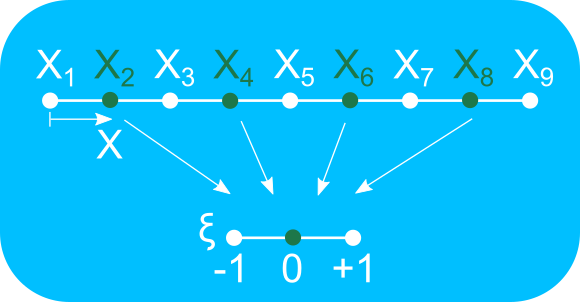

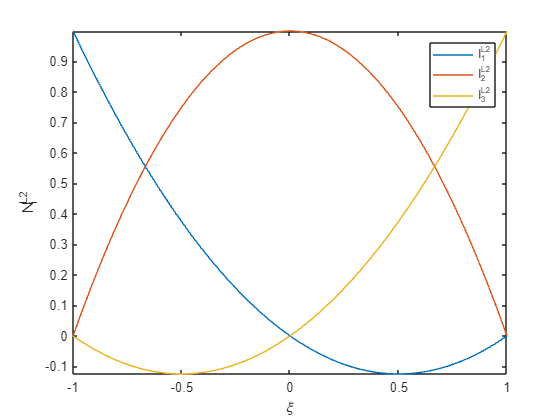

syms xi N1L2(xi) N2L2(xi) N3L2(xi) NL2(xi)
N1L2(xi) = l1L2(xi, -1, 0, +1);
N2L2(xi) = l2L2(xi, -1, 0, +1);
N3L2(xi) = l3L2(xi, -1, 0, +1);
NL2(xi) = [N1L2(xi) N2L2(xi) N3L2(xi)];
fplot(NL2, [-1 +1])
legend(["l_1^{L2}", "l_2^{L2}", "l_3^{L2}"]);
xlabel("\xi")
ylabel("N_i^{L2}")